# Parallelization of Antenna and Array Analyses

This example shows how to speed up antenna and array analysis using Parallel Computing Toolbox™.

Analyzing antenna performance over a frequency band is an important part of antenna design. There are various analysis methods that are supported by Antenna Toolbox™:

- Port analyses include `impedance`, `returnLoss`, `sparameters`, `vswr`, `efficiency`, `resonantFrequency`, and `bandwidth`.

- Surface analyses include `current`, `feedCurrent`, and `charge`.

- Field analyses include `pattern` and its variations, `EHfields`, `axialRatio`, and `beamwidth`. 

This example demonstrates the advantages of parallel computing for computing axial ratio and return loss over a frequency band. For axial ratio, we illustrate the manual setup of `parfor` for speeding up calculations. For return loss, we show how the `UseParallel` option, which is supported for all port analysis methods, can be used to automatically enable parallel computing.

## Axial Ratio Computation without Parallel Computing

Compute the axial ratio of an Archimedean spiral over a frequency band of 0.8 to 2.5 GHz in steps of 100 MHz. Perform this calculation serially, and save the time taken to perform these computations in variable `time1`.

sp = spiralArchimedean(Turns=4,InnerRadius=5.5e-3,OuterRadius=50e-3);
freq = 0.8e9:100e6:2.5e9;
AR = zeros(size(freq));
tic
for m = 1:numel(freq)
    AR(m) = axialRatio(sp,freq(m),0,90);
end
time1 = toc;

## Axial Ratio Computation with Parallel Computing

Repeat the calculations using Parallel Computing Toolbox to reduce computation time. Use the function `parpool` to create a parallel pool cluster. Then, use `parfor` to calculate the axial ratio over the same frequency band. The time taken to perform the computation is saved in variable `time2`.

pardata = parpool;

Starting parallel pool (parpool) using the 'Processes' profile ...
04-Oct-2024 13:28:31: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 8 workers.


sp = spiralArchimedean(Turns=4,InnerRadius=5.5e-3,OuterRadius=50e-3);
ARparfor = zeros(size(freq));
tic
parfor m = 1:numel(freq)
    ARparfor(m) = axialRatio(sp,freq(m),0,90);
end
time2 = toc;

Sometimes `parfor` will be slower on the first run because the code needs to become available to the workers. Re-run the code above for a second time to re-evaluate the elapsed time.

sp = spiralArchimedean(Turns=4,InnerRadius=5.5e-3,OuterRadius=50e-3);
ARparfor = zeros(size(freq));
tic
parfor m = 1:numel(freq)
    ARparfor(m) = axialRatio(sp,freq(m),0,90);
end
time2 = toc;

## Axial Ratio Computation Time Comparison

The table below shows the time taken for axial ratio analysis with and without Parallel Computing Toolbox. The cluster information is saved in the variable `pardata`.

cases = ["Without Parallel Computing" "With Parallel Computing"];
time  = [time1; time2];
numWorkers = [1; pardata.NumWorkers];
disp(table(time,numWorkers,RowNames=cases))

                                  time     numWorkers
                                  _____    __________

    Without Parallel Computing    5.371        1     
    With Parallel Computing       1.533        8     



disp("Speed-up due to parallel computing = " + time1/time2)

Speed-up due to parallel computing = 3.5036


The plot below shows the axial ratio data calculated for two cases. The results are identical.

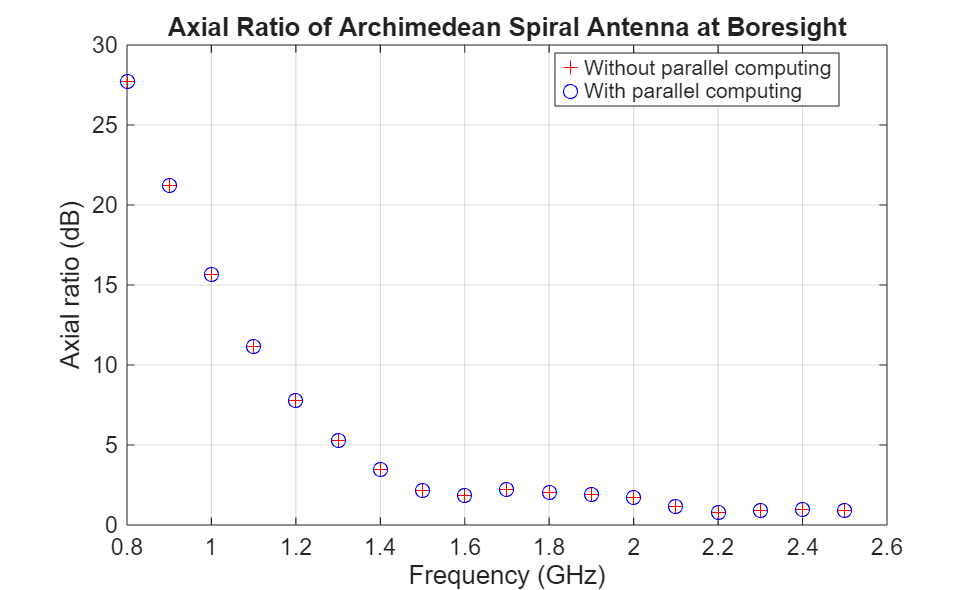

plot(freq./1e9, AR,"r+", freq./1e9, ARparfor,"bo")
grid on
xlabel("Frequency (GHz)")
ylabel("Axial ratio (dB)")
title("Axial Ratio of Archimedean Spiral Antenna at Boresight")
legend("Without parallel computing","With parallel computing", ...
    location="Best")

During this analysis the antenna structure is meshed at every frequency and then the far-fields are computed at that frequency to compute the axial ratio. One way of reducing the analysis time is to mesh the structure manually by specifying a maximum edge length.

## Return Loss Computation without Parallel Computing

The previous section performed a field analysis computation. All field and surface analysis computations in Antenna Toolbox™ accept only scalar frequency as input. However, `returnLoss` and all other port analysis functions accept a frequency vector as input. 

When a frequency vector is specified as an input, the antenna structure is meshed at the highest frequency. The resulting mesh is used for performing the analysis over the specified frequency band. The CPU time taken to perform the computation is saved in variable `time3`.

sp = spiralArchimedean(Turns=4,InnerRadius=5.5e-3,OuterRadius=50e-3);
tic
RL = returnLoss(sp,freq);
time3 = toc;

## Return Loss Computation with Parallel Computing

To use parallel computing to compute the return loss, set `UseParallel` to true. The time taken to perform the computation is saved in variable `time4`.

Alternatively, to manually set up a `parfor` loop for return loss calculations, mesh the structure at the highest frequency and use the `parfor` loop to run a frequency sweep. You cannot use the `parfor` loop by passing a single frequency at a time (as shown in the discussion about `axialRatio`) because the meshing happens at every frequency, limiting the advantage of parallel computing and potentially producing different results from the computations performed without parallel computing.The solution is to run the analysis at the highest frequency first, get the mesh information using the [`MeshReader`](docid:antenna_ref#mw_44ca46ae-82aa-4820-809d-b942d339bfec) object, and use the maximum edge length in the mesh to ensure the same mesh is used for all the computations.

sp = spiralArchimedean(Turns=4,InnerRadius=5.5e-3,OuterRadius=50e-3);
switch "Automatic parfor"
    case "Automatic parfor"
        tic
        RLparfor = returnLoss(sp,freq,UseParallel=true);
        time4 = toc;
    case "Manual parfor"
        RLparfor = zeros(size(freq));
        tic
        RLparfor(end) = returnLoss(sp,freq(end));
        meshdata = mesh(sp);
        [~] = mesh(sp, MaxEdgeLength=meshdata.MaxEdgeLength);
        parfor m = 1:(numel(freq)-1)
            RLparfor(m) = returnLoss(sp,freq(m));
        end
        time4 = toc;
end

## Return Loss Computation Time Comparison

The table below indicates the time taken for calculating the return loss with and without Parallel Computing Toolbox. The cluster information is saved in the variable `pardata`.

cases = ["Without Parallel Computing";"With Parallel Computing"];
time  = [time3; time4];
numWorkers = [1; pardata.NumWorkers];
disp(table(time,numWorkers,RowNames=cases))

                                   time     numWorkers
                                  ______    __________

    Without Parallel Computing    4.0974        1     
    With Parallel Computing       3.9948        8     



disp("Speed-up due to parallel computing = " + time3/time4)

Speed-up due to parallel computing = 1.0257


The plot below shows the return loss data calculated for two cases. The results are identical.

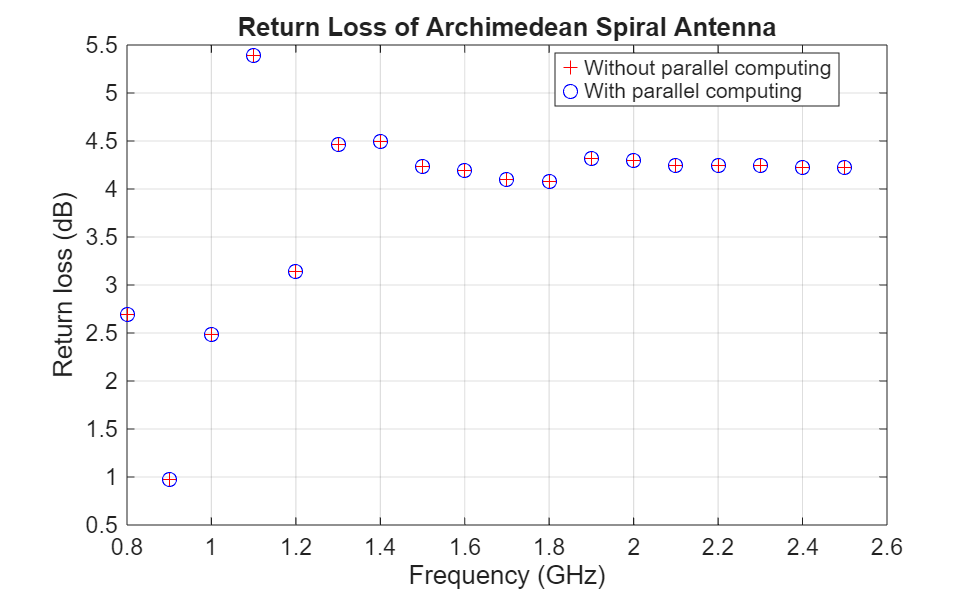

plot(freq./1e9, RL,"r+", freq./1e9, RLparfor,"bo")
grid on
xlabel("Frequency (GHz)")
ylabel("Return loss (dB)")
title("Return Loss of Archimedean Spiral Antenna")
legend("Without parallel computing","With parallel computing", ...
     location="Best")

Delete the current parallel pool.

delete(gcp)

Parallel pool using the 'Processes' profile is shutting down.


*Copyright 2014-23 The MathWorks, Inc.*